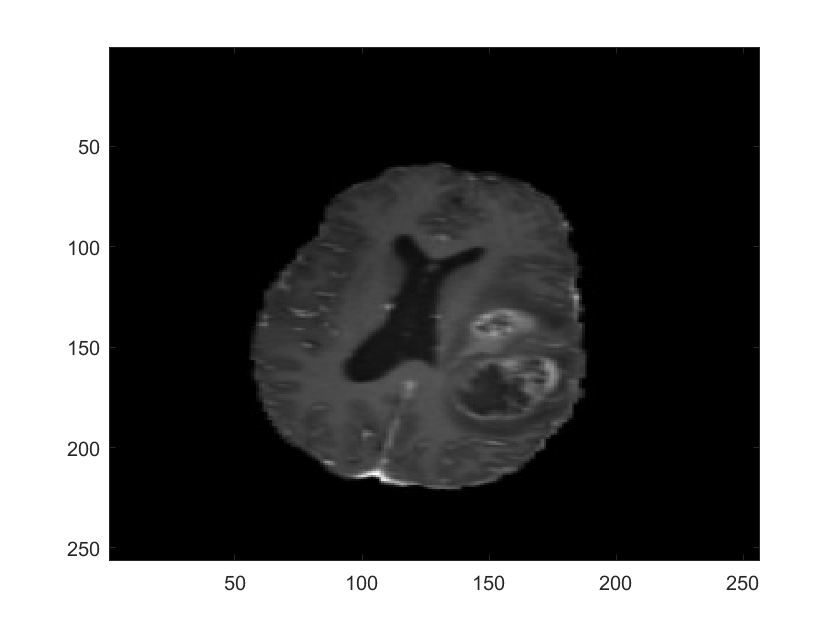


img = double(imread("axial_t1wce_2_class\images\test\00018_101.jpg"));
imagesc(img)
colormap 'gray'


list_dir = dir("axial_t1wce_2_class\images\test");


test = zeros(length(list_dir), 256^2);
good_images = [];

for i = 3:length(list_dir)
    f_name = "axial_t1wce_2_class\images\test\" + list_dir(i).name;
    img = imread(f_name);
    img = reshape(img, 1, []);
    if length(img) == (256^2)
        test(i, :) = img;
        good_images(end+1) = i;
    end
end

test = test(good_images, :);


list_dir = dir("axial_t1wce_2_class\images\train");


train = zeros(length(list_dir), 256^2);
good_images = [];

for i = 3:length(list_dir)
    f_name = "axial_t1wce_2_class\images\train\" + list_dir(i).name;
    img = imread(f_name);
    img = reshape(img, 1, []);
    if length(img) == (256^2)
        train(i, :) = img;
        good_images(end+1) = i;
    end
end

train = train(good_images, :);
